## Performance Analysis - RLS Combiner (Hourly, Daily, Monthly)

dt = testsetdt;    % DateTime of the test dataset
errors = eRLS(:);

figure;
time24 = dt.Hour + 1; % Time = 1...24 hrs
[dnum, dname] = weekday(dt, 'long');
labeld = {'Monday', 'Tuesday', 'Wednesday', 'Thursday', 'Friday', 'Saturday', 'Sunday'};
labelm = {'Jan', 'Feb', 'Mar', 'Apr', 'May', 'Jun', 'Jul', 'Aug',...
          'Sep', 'Oct', 'Nov', 'Dec'};

t = tiledlayout(2,3);
t.Padding = 'compact';     % uses all the spaces in the figure window
t.TileSpacing = 'compact';
sgt = sgtitle("Performance of the RLS CNN Algorithm - Errors, Absolute Percent Errors");
sgt.FontSize = 20;
warning('off', 'MATLAB:handle_graphics:Layout:NoPositionSetInTiledChartLayout');


### Box plots of the error distribution

% Hourly
sp(1) = nexttile;
boxplot(errors, time24)
title('Hourly Horizon')

% Daily
xtick = [7,1,2,3,4,5,6];    % the position we want them displayed as, i.e Mon - Sun
sp(2) = nexttile;
boxplot(errors, dnum,'positions', xtick)
set(gca, 'XTickLabel', labeld)
title('Daily Horizon')

% Monthly
sp(3) = nexttile;
boxplot(errors, dt.Month, 'Labels', labelm)
title('Monthly Horizon')

linkaxes(sp, 'y')
clear sp


### Absolute Percent Errors plot

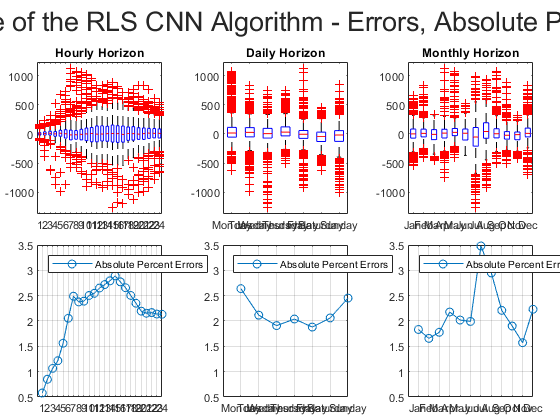

APEs = rls_APEs(:);

% Hourly
sp(1) = nexttile(4);
stats = grpstats(APEs, dt.Hour, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:24)
legend('Absolute Percent Errors', 'Location','northwest')
grid on

sp(2) = nexttile(5);
stats = grpstats(APEs, dnum, "mean");
stats = [stats(2:7); stats(1)];     % aligns for Mon - Sun
plot(stats, '-o')
set(gca,'XTick',1:1:7)
set(gca, "XTickLabel", labeld)
legend('Absolute Percent Errors', 'Location','northwest')
grid on

sp(3) = nexttile(6);
stats = grpstats(APEs, dt.Month, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:12)
set(gca,'XTickLabel', labelm)
legend('Absolute Percent Errors', 'Location','northwest')
grid on
linkaxes(sp, 'y')